# Home Ground Advantage

## Import data

EPL = readtable('EPLresults.csv');

Compute home and away goal difference.

GDH = EPL.HomeGF - EPL.HomeGA;
GDA = EPL.AwayGF - EPL.AwayGA;

## Compare Home vs. Away

moreHomeWins = EPL.HomeWins > EPL.AwayWins;

scatter(GDH(moreHomeWins),GDA(moreHomeWins))
hold on
scatter(GDH(~moreHomeWins),GDA(~moreHomeWins))
hold off

Annotates the plot and add the diagonal line.

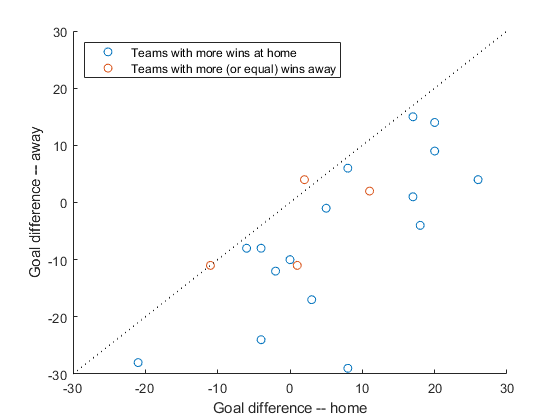

xlabel('Goal difference -- home')
ylabel('Goal difference -- away')
legend('Teams with more wins at home','Teams with more (or equal) wins away','AutoUpdate','off','Location','northwest')
hold on
plot([-30 30],[-30 30],'k:')
hold off